# Lagrangian Approximations for the Stochastic Reachability of a Target Tube

This example will demonstrate how to use the SReachTools toolbox to compute over and under approximations for the stochastic reachability of a target tube (SRTT) via Lagrangian methods.

## Lagrangian Methods

Lagrangian methods perform computations with sets using operations like unions, intersection, Minkowski addition/differences, etc. This computation using set operations can be used to approximate (either over or under) the SRTT problem. 

Advantages of Lagrangian:

- No gridding, which partially evades the curse of dimensionality

- Provides verification for closed-loop feedback strategies

Disadvantages:

- Using Polyhedral representation, must solve the vertex-facet enumeration problem, limiting computations to ~4 dimensional systems

- Does not provide an explicit control policy, only verifies the existence

This example uses the theoretical work from:

For underapproximations:

- J. D. Gleason, A. P. Vinod, M. M. K. Oishi, "Underapproximation of Reach-Avoid Sets for Discrete-Time Stochastic Systems via Lagrangian Methods," in Proceedings of the IEEE Conference on Decision and Control, 2017. 

For overapproximations: Unpublished but soon to be submitted

## Problem Definition

In this example we will look at the viability problem for a double integrator. The system dynamics are:


$$  x_{k+1} = \left[ \begin{array}{cc}
    1 & T \\
    0 & 1
  \end{array}\right] x_{k} + \left[\begin{array}{c}
    \frac{T^{2}}{2} \\
    T
  \end{array}\right] u_{k} + w_{k}$$


where $x_{k+1} \in \mathbb{R}^{2}$ is the state, $u_{k} \in \mathbb{R}$ is the input, and $w_{k} \in \mathbb{R}^{2}$ is the disturbance. The following code defines this system with $w_{k}$ as an i.i.d. Gaussian disturbance with mean $[0, 0]^{\top}$ and variance $\mathrm{diag}(0.01, 0.01)$.

% example parameters
T = 0.25;

% define the system
sys = getChainOfIntegLtiSystem(2, ...
    T, ...
    Polyhedron('lb', -0.1, 'ub', 0.1), ...
     StochasticDisturbance('Gaussian', zeros(2,1), 0.001*eye(2)));


We examine the viability problem in which we are interested in staying in a set of safe states. In this example the safe set is $\{x \in \mathbb{R}^{2}: |x_{i}| < 1, i = 1, 2\}$. For the SRTT problem the viability problem is formed by constructing a target tube in which all sets in the tube are the safe set.

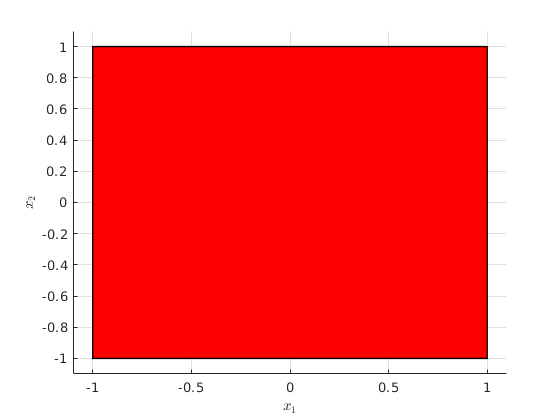

% safe set definition
safe_set = Polyhedron('lb', [-1, -1], 'ub', [1, 1]);

plot(safe_set)
xlabel('$x_1$', 'Interpreter', 'latex')
ylabel('$x_2$', 'Interpreter', 'latex')


% safe sets
target_tube = {safe_set, ...
    safe_set, ...
    safe_set, ...
    safe_set, ...
    safe_set};

N = length(target_tube);

For the Lagrangian methods we compute robust and augmented effective target sets---for the under and overapproximations, respectively. For this computation we need to convert the Gaussian disturbance into a bounded distrubance set which will satisfy the required conditions detailed in the aforementioned papers. We do this here for a an 0.8 probability with the given target tube.

There are several ways to create bounded disturbance sets. Here, we formulate a bounded disturbance by creating a polyhedral approximation of an ellipsoid through random direction choices.

% probability threshold desired
beta = 0.8;

% bounded set for Lagrangian
lag_bounded_set = getBoundedSetForDisturbance(sys.disturbance, N, beta, ...
    'random', 50);

Now we can compute the Lagrangian under and overapproximations which we call the robust and augmented effective target sets

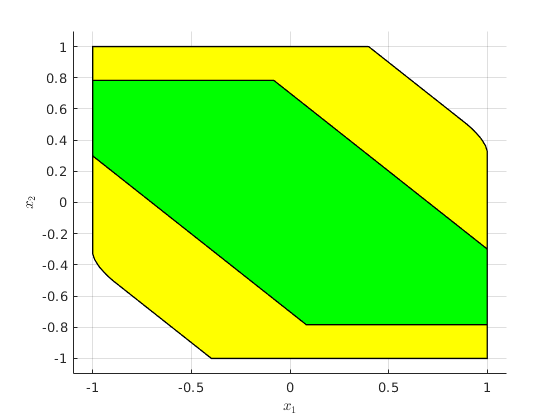

robust_eff_target = getRobustEffTarget(sys, target_tube, lag_bounded_set);
aug_eff_target    = getAugEffTarget(sys, target_tube, lag_bounded_set);

plot(aug_eff_target, 'color', 'y');
hold on;
plot(robust_eff_target, 'color', 'g');
hold off;
xlabel('$x_1$', 'Interpreter', 'latex')
ylabel('$x_2$', 'Interpreter', 'latex')

The above functions, i.e. computing the bounded set and determining the over and under approximations have been combined into one function for convenience.

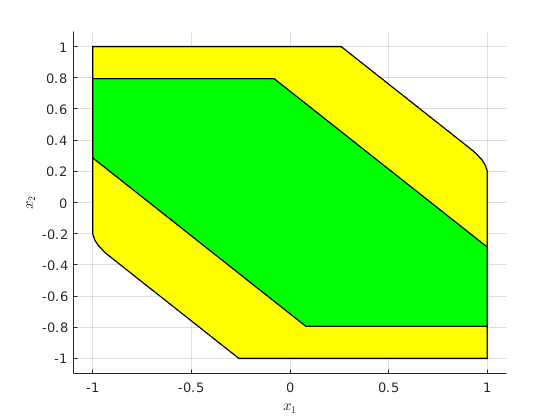

tic;
robust_target_2 = getApproxStochasticLevelSetViaLagrangian(sys, ...
    beta, target_tube, 'underapproximation', 'random', 50);
aug_target_2    = getApproxStochasticLevelSetViaLagrangian(sys, ...
    beta, target_tube, 'overapproximation', 'random', 50);
lagrange_time = toc();

plot(aug_target_2, 'color', 'y');
hold on;
plot(robust_target_2, 'color', 'g');
hold off;
xlabel('$x_1$', 'Interpreter', 'latex')
ylabel('$x_2$', 'Interpreter', 'latex')

Because of the choice or random directions for the ellipse `robust_eff_target` and `robust_target_2` are not exactly equivalent (same for the augmented sets). However they can be seen to be visually near identical.

We can compare the results with dynamic programming to see how the approximations appear and how they compare in simulation times. The dynamic programming methods use an 80x80x10 ($x_1\times x_{2} \times u$) grid.

% need to create a state space grid and input space grid
ss_grid = SpaceGrid([-1, -1], [1, 1], 80);
in_grid = InputGrid(-0.1, 0.1, 10);

tic;
grid_probability = getDynProgSolForTargetTube(sys, ...
    ss_grid, in_grid, target_tube);
dynprog_time = toc();

The simulation timies for lagrangian computation is much faster than dynamic programming, even when computing both approximations.

lagrange_time

lagrange_time = 0.2675

dynprog_time

dynprog_time = 145.6234

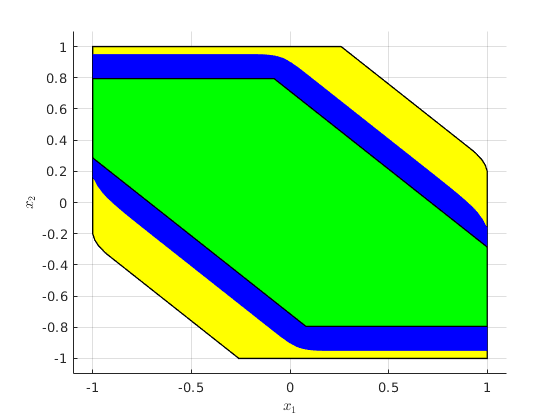

% plotting
[X,Y] = ss_grid.getMeshGrids();
plot(aug_target_2, 'color', 'y');
hold on;
contourf(X,Y,reshape(grid_probability, size(X)), [0.8,0.8], ...
    'color', 'b', 'facecolor', 'b')
plot(robust_target_2, 'color', 'g');
hold off;
xlabel('$x_1$', 'Interpreter', 'latex')
ylabel('$x_2$', 'Interpreter', 'latex')